# Laboratory 2: Step Response 

**Objective: **To use MATLAB as a tool to simulate the step response of the following transfer functions of the system

**Background:**

*Transfer Function: *

    Imagine your system is a black box. You put something in (the input), and you get something out (the output). The transfer function, written as a fancy capital G(s), is a mathematical recipe that tells you exactly how that black box transforms the input into the output. It's like a secret formula that depends on the inner workings of the system.

Here's the technical part: The transfer function uses Laplace transforms (don't worry, these transforms turn functions of time into functions of a variable 's'). It expresses the output (Y(s)) as a fraction of the input (X(s)) based on the system's properties.

*Step Response: *

This is where things get interesting for your lab. The step response is what happens to the output (y(t)) when you give the system a very specific input: a sudden jump from zero to a constant value (like flipping a light switch on). It's like a test question for your system, revealing how it reacts to a quick change.

By analyzing the step response (a graph of y(t) vs. time), you can learn a lot about the system. Does it reach the final output value quickly? Does it oscillate before settling? The shape of the curve tells you things like the system's stability, speed, and accuracy.

*Why are they important in your lab?*

By understanding the transfer function (the recipe) and observing the step response (the result), you can:

Predict system behavior: You can use the transfer function to anticipate how the system will react to different inputs, not just a step change.

Diagnose problems: A wonky step response can indicate issues with your system's components.

Tune and improve the system: By analyzing the step response, you can see how to adjust the system to get the desired output.

**Procedure:**

- Define the following transfer functions in MATLAB using the tf function or by specifying the numerator and denominator coefficients.

- Plot the step responses using the step function.

- Then use simulink to plot the step responses. Also apply sinusoidal source and compare the response.

## **Zeroes and Poles of a Transfer Function**

In study of Transfer Functions, it is very important what are zeroes and poles of transfer function may be.

If the Transfer Function G(s) = Y(s)/X(s).

    ***Zeroes.*** It defines as roots of the numerators or mathematically speaking Y(s) = 0. If we reach the limit of the following zeroes of the transfer function. G(s) will appraoch to zero.

    ***Poles. ***It defines as the roots of the denominator or mathetmatically speaking X(s) = 0. If we reach the limite of the following poles of the transfer function. G(s) will approach to infinity.

    Zeroes and Poles are very crucial on identifying how the dynamics system of mechanical, electrical or electromechanical vary respond to different disturbances.

## **Transfer Functions and its Differential Equations Equivalent: System Response.**

As previous discussions by Mr. Amboy in his Differential Equations series, We tackled the different types of Differential Equations before the First Major Examinations. These are known as First Order Linear Equations which involves a constant steady state response. Linear First Order Systems take a Single Derivative on the Equation itself. They are easy to calculate on hand.

In Linear Constant Coefficients Differential Equations (LCCDE) in Second Order, he emaphasizes the differences of the following responses depends on the Damping Ratio 

    *Undamped. *Damping Ratio = 0

    *Underdamped. 0 < *Damping Ratio < 1

*    Critically Damped. *Damping Ratio  = 1

*    Overdamped. *Damping Ratio > 1

These are known for having two Derivatives in a given Systems. 

In Later Lessons in depth on Control Systems, Non Linear Control Systems May discuss as if it is the real description and not approximation of the real dynamic systems. 

## First Order System

We describe the first order system in this code:

eq1 = tf(1, [1,1])

eq1 =
 
    1
  -----
  s + 1
 
Continuous-time transfer function.
Model Properties


And we get its step response via step()

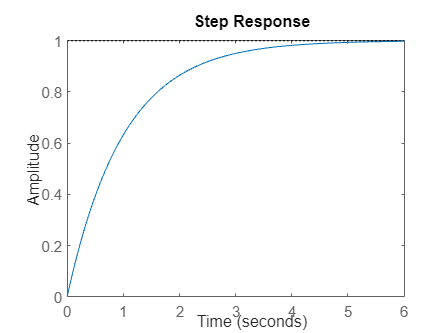

step(eq1)

## **Second Order System**

We describe the three types of Second Order System involved in this laboratory

### Underdamped

underdamp = tf(1, [1, 2, 1])

underdamp =
 
        1
  -------------
  s^2 + 2 s + 1
 
Continuous-time transfer function.
Model Properties


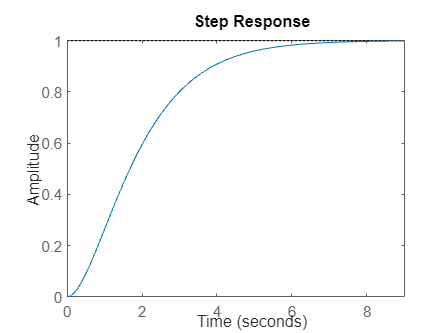

step(underdamp)

### Critically Damped

critdamp = tf(1, [1, 5, 6])

critdamp =
 
        1
  -------------
  s^2 + 5 s + 6
 
Continuous-time transfer function.
Model Properties


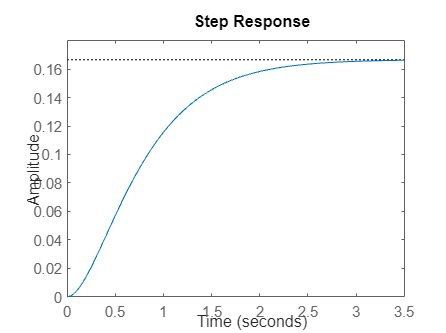

step(critdamp)

### Overdamped

overdamp = tf(1, [1, 2, 1])

overdamp =
 
        1
  -------------
  s^2 + 2 s + 1
 
Continuous-time transfer function.
Model Properties


step(overdamp)

### Resonant System

resonant = tf([8,7,6,5,4,3,2],[1,2,3,4,5,6,7,1])

resonant =
 
     8 s^6 + 7 s^5 + 6 s^4 + 5 s^3 + 4 s^2 + 3 s + 2
  -----------------------------------------------------
  s^7 + 2 s^6 + 3 s^5 + 4 s^4 + 5 s^3 + 6 s^2 + 7 s + 1
 
Continuous-time transfer function.
Model Properties


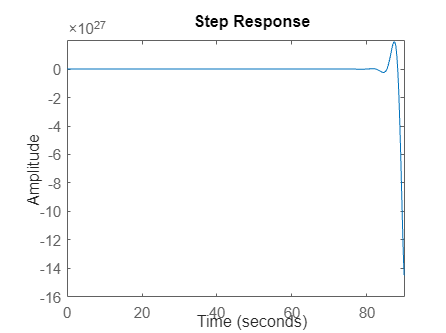

step(resonant)

### Electrical Filter with Multiple Poles

elex_filter = tf([4,3,2,1], [1,2,3,4,1])

elex_filter =
 
     4 s^3 + 3 s^2 + 2 s + 1
  -----------------------------
  s^4 + 2 s^3 + 3 s^2 + 4 s + 1
 
Continuous-time transfer function.
Model Properties


step(resonant)

### Plant with Time Delay

plant_delay = tf([6,5,4,3,2], [1,2,3,4,5,1], 'InputDelay', 2.1)

plant_delay =
 
                   6 s^4 + 5 s^3 + 4 s^2 + 3 s + 2
  exp(-2.1*s) * -------------------------------------
                s^5 + 2 s^4 + 3 s^3 + 4 s^2 + 5 s + 1
 
Continuous-time transfer function.
Model Properties


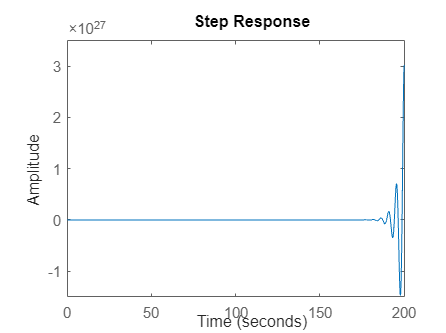

step(plant_delay)

### Nonlinear System Approximation

nonlinear = tf([10,8,6,4,2], [1,3,5,7,9,1])

nonlinear =
 
    10 s^4 + 8 s^3 + 6 s^2 + 4 s + 2
  -------------------------------------
  s^5 + 3 s^4 + 5 s^3 + 7 s^2 + 9 s + 1
 
Continuous-time transfer function.
Model Properties


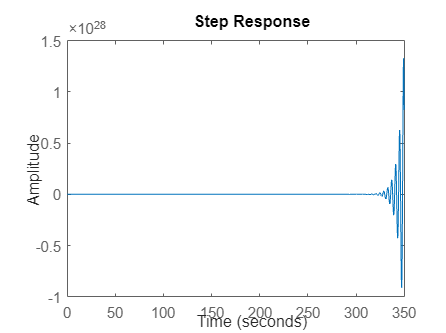

step(nonlinear)